In this practice we use advanced mathematical morphology concepts applied to the problem of **extracting the most important objects of an image**, also known as **image segmentation**.

#### Watershed Algorithm

One of the simplest techniques for segmentation is the **watershed**. In hydrology this word means the topographical boundary dividing two adjacent drainage basin, such as a ridge or a crest. A drainage basin is the geographical region in which all water drains (for example, when it rains) to the same river.

As we know, in mathematical morphology a grayscale image is interpreted as a topographic relief. The watershed segmentation algorithm extracts the watershed of the image through a process of flooding. In particular, the landscape is gradually flooded and when the water from two valleys contact (water overflows a basin), the algorithm places a barrier or dam to prevent water redistribution (mixing). The output image is formed by the different basins (each with a different label) and the set of dams or edges that delimit the basins.

You can use the watershed2 function provided in the lab files.

%y = wathershed(Image, conn)

The input image should be in grayscale, so we should read the image, and in the case that is in rgb we should convert  it to grayscale.

% read the image
x=im2double(imread('dem.gif'));
% Apply watershed with 8-connectivity in this case.
y= watershed2(x*255,8);

In order to visualize  the obtained segmentation, you can use the label2rgb function from matlab.

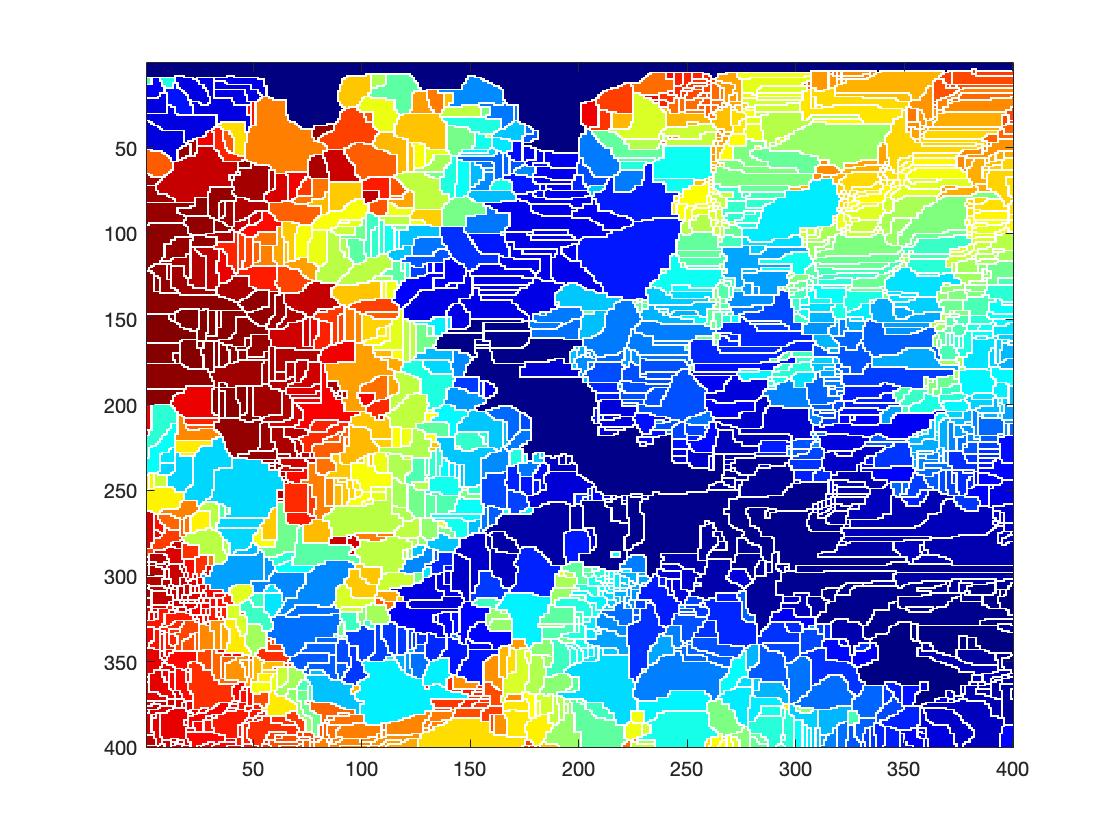

% use the label2rgb functino to convert the label image into a RGB image.
color_map = label2rgb(y);

imagesc(color_map)